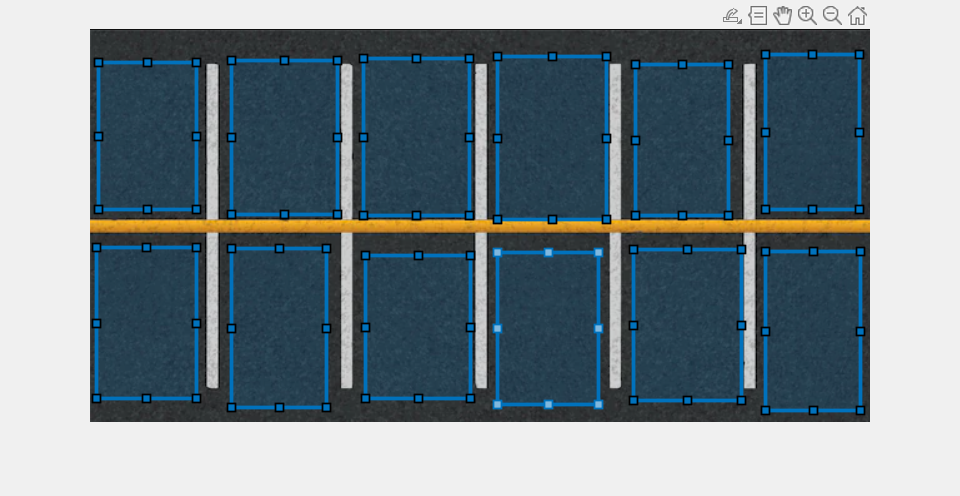

clc;clear;close all;
image = imread('empty.png');
imshow(image);
rectangles = {};
flag = true;
while flag
    rect = drawrectangle();
    rectangles{end+1} = rect;
    choice = questdlg('Do you want to add another rectangle?');
    if strcmp(choice,'No')
        flag = false;
    end
end

mask = zeros(size(image,1),size(image,2));
for i = 1:length(rectangles)
    h=rectangles{i};
    position = round(h.Position);
    mask(position(2):position(2)+position(4),position(1):position(1)+position(3)) = 1;
end
ROIs = image .* uint8(repmat(mask, [1 1 3]));
%disp(rectangles)
imwrite(mask,"mask.png");
% load the fiiled image
% Load the image
image = imread('filled5.png');

% Initialize the counter
occupiedSlots = 0;

% Use a for loop to iterate over the rectangles
for i = 1:length(rectangles)
    k=rectangles{i};
    position = round(k.Position);
    roi = image(position(2) : position(2) + position(4), position(1) : position(1) + position(3), :);
    % Check if the ROI is not all black (indicating that it is occupied)
    if sum(sum(sum(roi))) ~= 0
        occupiedSlots = occupiedSlots + 1;
    end
end

% Print the result
fprintf('Number of occupied slots: %d\n', occupiedSlots);

Number of occupied slots: 12
